# How to use GPU (GPU使用指南)

% Bulit on 2022.7.11 by Fred Liu

#### 查看GPU列表(GPU Table)

gpuDeviceTable

ans = 1×5 table
    Index           Name           ComputeCapability    DeviceAvailable    DeviceSelected
    _____    __________________    _________________    _______________    ______________

      1      "GeForce RTX 3090"          "8.6"               true              true      


#### 目前使用的GPU(GPU Inuse)

gpuDeviceCount

ans = 1

#### 檢視GPU狀況(View GPU Status)

gpuDevice

ans =   CUDADevice with properties:

                      Name: 'GeForce RTX 3090'
                     Index: 1
         ComputeCapability: '8.6'
            SupportsDouble: 1
             DriverVersion: 11.2000
            ToolkitVersion: 11.2000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 2.5770e+10
           AvailableMemory: 2.4193e+10
       MultiprocessorCount: 82
              ClockRateKHz: 1860000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


#### 更改指定使用的GPU(Change GPU)

gpuDevice(2)
gpuDeviceCount

# 使用GPU Array加速

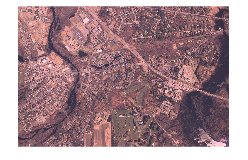

imOriginal = imread('concordaerial.png');
imshow(imOriginal)


imGPUoriginal = gpuArray(imOriginal);

#### 不使用GPU Array

tic
imgray = rgb2gray(imOriginal);
imbw = imgray < 70;
imWaterMask = imopen(imbw,strel('disk',5));
toc

Elapsed time is 0.019691 seconds.


#### 使用GPU Array

tic
imGPUgray = rgb2gray(imGPUoriginal);
imWaterGPU =imGPUgray < 70;
imGPUWaterMask = imopen(imWaterGPU,strel('disk',5));
toc

Elapsed time is 0.011398 seconds.


# 測試GPU Coder環境

gpucoderSetup

Error using gpucoderSetup
GPU
Environment
Check
application
is
already
running.